## Open or consolidate data files

open the excel files with the test data to generate the database

clear
is_Mac = 0;
consolidate = 1;

addpath(genpath(fullfile(pwd,'sw')))
save_path = fullfile(fileparts(pwd),'Data\flight_data_VSQP\static_test_1905\database\general');
data_path = fullfile(fileparts(pwd),'Data\flight_data_VSQP\static_test_1905\database\single');


unit_header = ["ID","Item","Windspeed [m/s]","Airspeed [m/s]","Skew [deg]","Skew_sp [deg]","Mot_Status","Excitation","Mx [Nm]","My [Nm]","Mz [Nm]","Fx [N]","Fy[N]","Fz [N]","Mot_F [pwm]","Mot_R [pwm]","Mot_B [pwm]","Mot_L [pwm]","Ail_L [pwm]","Ail_R [pwm]","Elev [pwm]","Rud [pwm]","Pitch [deg]"];    
database_header = ["ID","Item","Windspeed","Airspeed","Skew","Skew_sp","Mot_Status","Excitation","Mx","My","Mz","Fx","Fy","Fz","Mot_F","Mot_R","Mot_B","Mot_L","Ail_L","Ail_R","Elev","Rud","Pitch"];
if consolidate
    xlsxFiles = dir(fullfile(data_path,'*.xlsx')); 
    numfiles = length(xlsxFiles);
    mydata = cell(1, numfiles);
    all    = [];
    for k = 1:numfiles 
      mydata{k} = xlsread(fullfile(data_path,xlsxFiles(k).name)); 
      all = [all;mydata{k}];
    end
    Table = array2table(all,'VariableNames',database_header);
    name = 'static_test_3.xlsx';
    table_path_format = fullfile(save_path,name);
    writetable(Table,table_path_format); 
else
    xlsxFiles = dir(fullfile(save_path,'*.xlsx'));
    all = xlsread(fullfile(save_path,xlsxFiles.name)); 
    Table = array2table(all,'VariableNames',database_header);
end


## Perform transformation from balance to drone c.g. and apply calibration

data = Table;
path = fullfile(fileparts(pwd),'Data\flight_data_VSQP\static_test_1905\OJF\calibration');

name = strcat('calibration.txt');
fid = fopen(fullfile(path,name));
format = sprintf('%s', repmat('%f', 1, 7));
calibration = cell2mat(textscan(fid, format,'Delimiter', ','));
fclose(fid);

for i =1:size(data,1)
    int_cal = interp1(calibration(:,1),calibration(:,2:end),data.Windspeed(i));
    data.Fx(i) = (data.Fx(i)-int_cal(1)).*(-1);
    data.Fy(i) = (data.Fy(i)-int_cal(2)).*(-1);
    data.Fz(i) = data.Fz(i)-int_cal(3);
    data.Mx(i) = (data.Mx(i)-int_cal(4)).*(-1);
    data.My(i) = (data.My(i)-int_cal(5)).*(-1);
    data.Mz(i) = data.Mz(i)-int_cal(6);
end

pole = [0,0,-1.2085].'; %[0,0,-1]90.5+5.5+8+16.85 -1.04
m_i  = [data.Mx,data.My,data.Mz];
f_i  = [data.Fx,data.Fy,data.Fz];
m_e  = m_i + cross(f_i,pole.'.*ones(size(f_i)));
data.Mx = m_e(:,1);
data.My = m_e(:,2);
data.Mz = m_e(:,3);
data2 = data;
% Rotated reference frame
data2.Fx = data.Fx;
data2.Fy = data.Fz;
data2.Fz = data.Fy.*(-1);
data2.Mx = data.Mx;
data2.My = data.Mz;
data2.Mz = data.My.*(-1);

## Filter out not filled data points

data2 = data2(data2.Windspeed<16,:);
data2.Pitch = round(data2.Pitch);
data2.Skew_sp = max(data2.Skew_sp,0);
data2.Windspeed = round(data2.Windspeed);

## Investigate the lifting properties of the wing

folder = fullfile(pwd,'plots_save');
baseline = 0 ;
baseline = baseline+k;
v = unique(data2.Windspeed);
leg_pitch = [];
for i=[-2,0,6,12,18]
    leg_pitch= [leg_pitch,strcat(string(i),'[deg]'),''];
end
pitches = unique(round(data2.Pitch));
v = unique(data2.Windspeed);
leg_skew = [];
skews_sp = unique(data2.Skew_sp);
skews_sp(1) = 0;
L = 0.5 * 1.225 * 1.56 * 0.235 ;
h = zeros(size(skews_sp));
visible = 1;
save_pictures = 1;
if visible
  f=figure(20);
else
  f=figure('visible','off');
end
t = tiledlayout(1,1);
clf
cla
nexttile
hold on
for i=1:max(size(skews_sp))
    leg_skew= [leg_skew,strcat(string(skews_sp(i)),'[deg]'),''];
    out  = table_sifter(data2,[-1,5,-1,-1,-1,skews_sp(i),0,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1]);
    CL   = -1.*out.Fz./(L*out.Windspeed.^2);
    [rmse_log,p_out,h] =plot_special_v2(out.Pitch,CL,-1,i,1,h);
end

lsqr converged at iteration 1 to a solution with relative residual 0.17.
lsqr converged at iteration 1 to a solution with relative residual 0.17.
lsqr converged at iteration 1 to a solution with relative residual 0.25.
lsqr converged at iteration 1 to a solution with relative residual 0.31.
lsqr converged at iteration 1 to a solution with relative residual 0.39.
lsqr converged at iteration 1 to a solution with relative residual 0.46.
lsqr stopped at iteration 50 without converging to the desired tolerance 1e-12
because the maximum number of iterations was reached.
The iterate returned (number 50) has relative residual NaN.


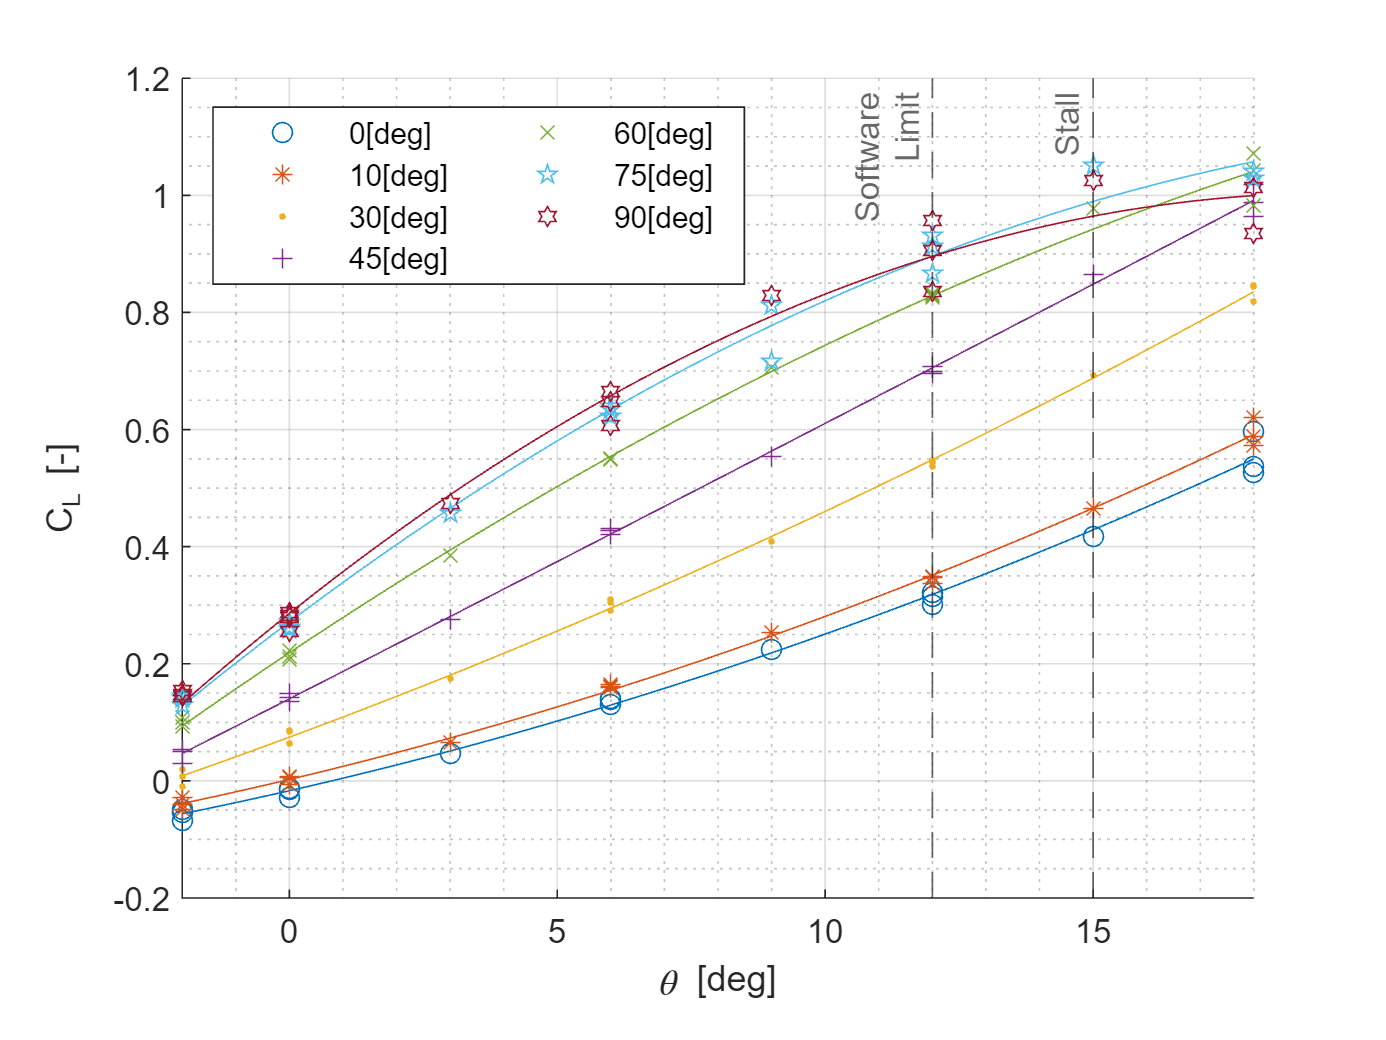

xline([12 15],'--',{{'Software';'Limit'},'Stall'},'LabelHorizontalAlignment','left','LabelVerticalAlignment',{'top'})
xlabel("\theta [deg]")
xlim([-2,18])
ylabel("C_L [-]")
grid on
grid minor
f.Units = 'inches';
f.OuterPosition = [0 0 5 4];
lgd = legend(leg_skew,'NumColumns',2,'Location','northwest');
s = strcat("Wing_CL_curve");
if save_pictures
    exportgraphics(f,fullfile(folder,strcat(s,'.pdf')),'ContentType','vector')
end

## Lift model for controller

prefilter = data2(data2.Pitch<12,:);
out  = table_sifter(prefilter,[-1,5,-1,-1,-1,-1,0,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1]);
gamma = L.*out.Windspeed.^2;
skew_f = deg2rad(out.Skew_sp);
pitch_f = deg2rad(out.Pitch);
p = gamma.*[pitch_f.*sin(skew_f).^2,sin(skew_f).^2,pitch_f,ones(size(skew_f))]\out.(14);
est = gamma.*(p(1).*pitch_f.*sin(skew_f).^2+p(2).*sin(skew_f).^2+p(3).*pitch_f+p(4).*ones(size(skew_f)));
RMSE = rms(out.(14)-est);